# Fundamentals of Linear Control

**Mauricio de Oliveira**

*Supplemental material for Chapter 5*

## Before You Start

In this script you will perform calculations with transfer-functions. In addition to the commands already used, the following MATLAB commands will be used:

- `ss,` to create state-space objects;

- `tzero`, to calculate the transmission zeros of a MIMO system.

 You will also use the following auxiliary commands:

- `minreal`, to perform pole-zero cancellations;

## 5.3 Minimal State-Space Realization

The command ss creates a state-space object that MATLAB can work with. The arguments of `ss` are the state-space realization (A,B,C,D) matrices. For example:

% State space model (5.9)
alpha = 1

alpha = 1

beta = 1

beta = 1

gamma = 1

gamma = 1


A = [0 1; 0 0]

A =      0     1
     0     0


B = [1; beta]

B =      1
     1


C = [alpha 1]

C =      1     1


D = gamma

D = 1


g = ss(A,B,C,D)

g =
 
  A = 
       x1  x2
   x1   0   1
   x2   0   0
 
  B = 
       u1
   x1   1
   x2   1
 
  C = 
       x1  x2
   y1   1   1
 
  D = 
       u1
   y1   1
 
Continuous-time state-space model.



construct a state-space object `g` that represents the transfer-function in (5.9).

One can transform back and forth between state-space and transfer-functions. For example, `tf` converts the state-space object into a transfer-function object:

% to transfer-function
tf(g)

ans =
 
  s^2 + 2 s + 1
  -------------
       s^2
 
Continuous-time transfer function.



One can directly calculate various properties of state-space objects without explicitly converting to transfer-function. For example:

pole(g)

ans =      0
     0


calculate the poles and 

zero(g)

ans =    -1.0000
   -1.0000


calculates the zeros of g.

One operates with state-space objects the same way as with transfer-function objects. For example the command `step` calculates the step response and produces a plot as in:

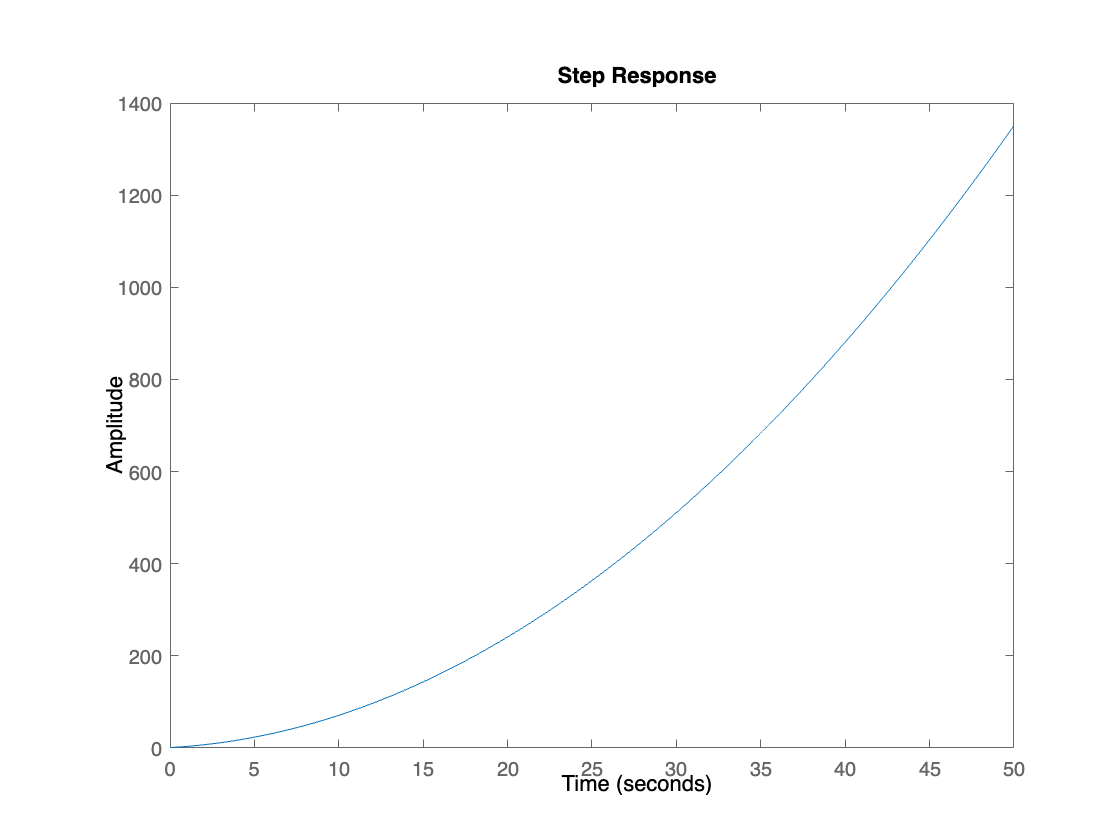

step(g)

and `bode` produces a representation of the frequency response (more about this on Chapter 7):

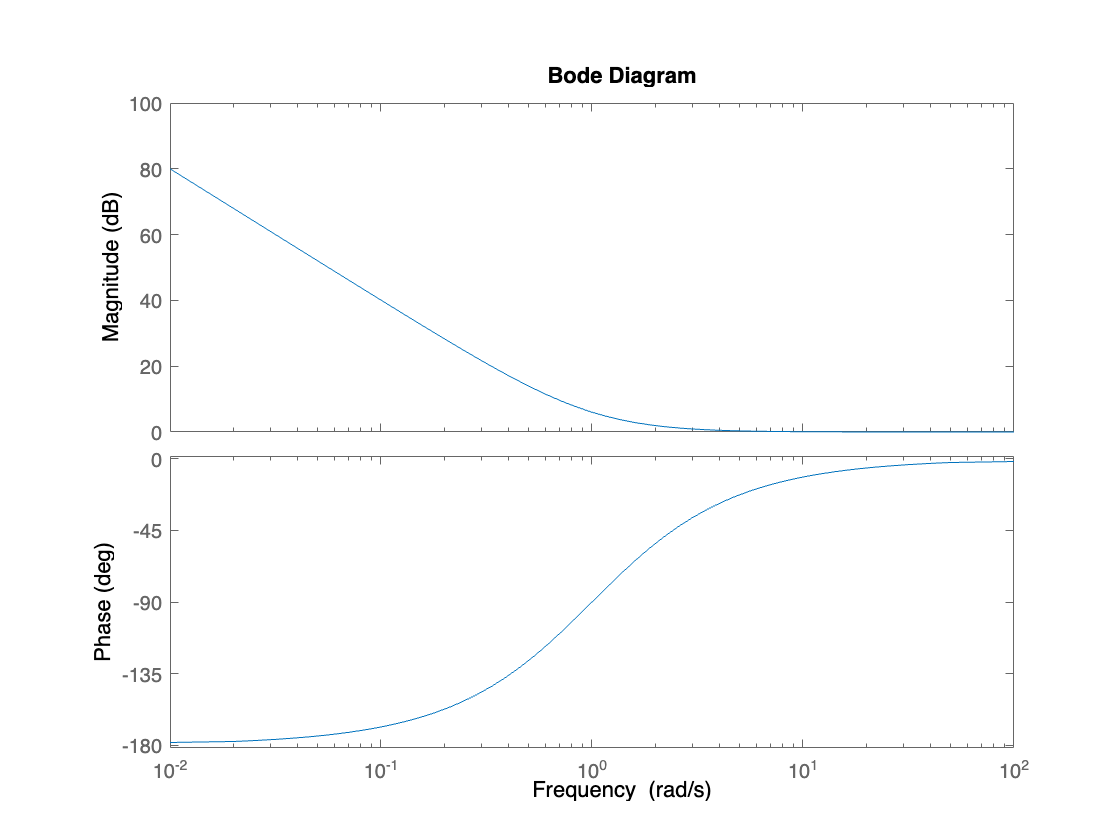

bode(g)

Note that the step response diverges since g is not asymptotically stable (it has two poles at the origin). It can be stabilized by unit feedback

h = feedback(g,1)

h =
 
  A = 
         x1    x2
   x1  -0.5   0.5
   x2  -0.5  -0.5
 
  B = 
        u1
   x1  0.5
   x2  0.5
 
  C = 
        x1   x2
   y1  0.5  0.5
 
  D = 
        u1
   y1  0.5
 
Continuous-time state-space model.



which produces a closed-loop system with poles at

pole(h)

ans =   -0.5000 + 0.5000i
  -0.5000 - 0.5000i


If we redo the calculation with

% Model (5.9)
alpha = 0;
beta = 1;
gamma = 1;

A = [0 1; 0 0];
B = [1; beta];
C = [alpha 1];
D = gamma;

g = ss(A,B,C,D)

g =
 
  A = 
       x1  x2
   x1   0   1
   x2   0   0
 
  B = 
       u1
   x1   1
   x2   1
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   1
 
Continuous-time state-space model.



and calculate the transfer-function

tf(g)

ans =
 
  s + 1
  -----
    s
 
Continuous-time transfer function.



note how the order of the transfer-function is now 1 instead of 2. As discussed in Section 5.3, the reason is lack of controllability.

A minimal realization associated with this state-space realization is obtained using:

minreal(g)

1 state removed.

ans =
 
  A = 
       x1
   x1   0
 
  B = 
       u1
   x1   1
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   1
 
Continuous-time state-space model.



Note that without controlability the system can no longer be stabilized under feedback. Indeed

h = feedback(g,1)

h =
 
  A = 
         x1    x2
   x1     0   0.5
   x2     0  -0.5
 
  B = 
        u1
   x1  0.5
   x2  0.5
 
  C = 
        x1   x2
   y1    0  0.5
 
  D = 
        u1
   y1  0.5
 
Continuous-time state-space model.



pole(h)

ans =    -0.5000
         0


reveal that one of the poles remain at the origin.

We can use the above commands to verify that the example (5.11)

% Model (5.11)
A = -eye(2);
B = 2*eye(2);
C = -[0 1/2;1 1/2];
D = [1 1; 1 1];

g = ss(A,B,C,D)

g =
 
  A = 
       x1  x2
   x1  -1   0
   x2   0  -1
 
  B = 
       u1  u2
   x1   2   0
   x2   0   2
 
  C = 
         x1    x2
   y1     0  -0.5
   y2    -1  -0.5
 
  D = 
       u1  u2
   y1   1   1
   y2   1   1
 
Continuous-time state-space model.



has the transfer-function shown in Section 5.3

% to transfer-function
tf(g)

ans =
 
  From input 1 to output...
   1:  1
 
       s - 1
   2:  -----
       s + 1
 
  From input 2 to output...
       s + 3.14e-16
   1:  ------------
          s + 1
 
       s + 3.14e-16
   2:  ------------
          s + 1
 
Continuous-time transfer function.



which appears to be of first order. We can calculate the poles

pole(g)

ans =     -1
    -1


and zeros

tzero(g)

ans = 0

Note that we use `tzero` because this is a MIMO system. A call to 

minreal(g)

ans =
 
  A = 
       x1  x2
   x1  -1   0
   x2   0  -1
 
  B = 
       u1  u2
   x1   2   0
   x2   0   2
 
  C = 
         x1    x2
   y1     0  -0.5
   y2    -1  -0.5
 
  D = 
       u1  u2
   y1   1   1
   y2   1   1
 
Continuous-time state-space model.



does not reduce the system since it is already minimal.

## 5.5 Simple Pendulum

Consider the simple pendulum with parameterrs:

m = 0.5

m = 0.5000

l = 0.3

l = 0.3000

r = l/2

r = 0.1500

b = 0

b = 0

g = 9.8

g = 9.8000

J = m*l^2/12

J = 0.0038

Jr = J + m*r^2

Jr = 0.0150

and the block-diagram corresponding to Fig. 5.12:

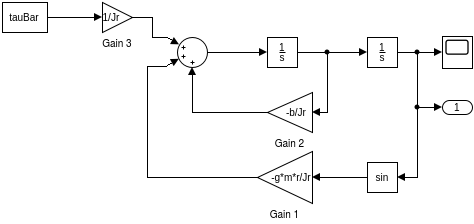

This diagram is implemented in simulink as the model 'SimplePendulumWithoutFeedback.mdl'. It can be simulated directly in simulink or using the commands:

T = 10     % Simulation time

T = 10

theta0 = pi/6 % Initial angle

theta0 = 0.5236

tauBar = 0 % External torque

tauBar = 0

[t,x,y]=sim(['SimplePendulumWithoutFeedback'], T);

The output $y$ corresponds to the angle $\theta$ that we plot next:

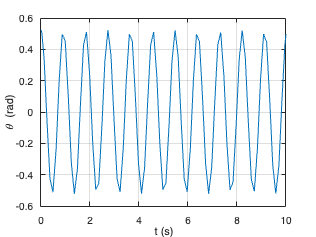

plot(t,y), grid
ylabel('\theta (rad)')
xlabel('t (s)')

Since there is no damping, $b = 0$, the behaviour in this case is that of an oscillator.

We can simulate other scenarios easily. For example, we can add damping:

b = 0.01

b = 0.0100

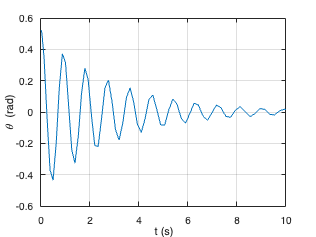

[t,x,y]=sim(['SimplePendulumWithoutFeedback'], T);

plot(t,y), grid
ylabel('\theta (rad)')
xlabel('t (s)')

or simulate starting near the unstable equilibrium $\theta = \pi$:

theta0 = pi-0.01 % Initial angle

theta0 = 3.1316

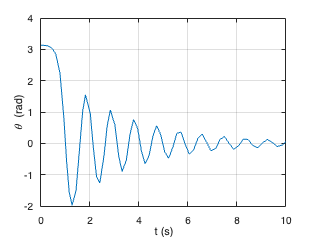

[t,x,y]=sim(['SimplePendulumWithoutFeedback'], T);

plot(t,y), grid
ylabel('\theta (rad)')
xlabel('t (s)')

which shows the pendulum diverging from that equilibrium towards the stable equilibrium $\theta = 0$. Likewise, we can add an external torque:

theta0 = 0   % Initial angle

theta0 = 0

tauBar = 0.1 % External torque

tauBar = 0.1000

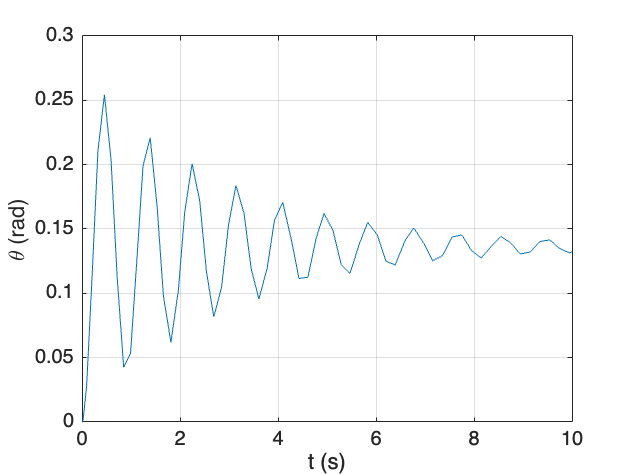

[t,x,y]=sim(['SimplePendulumWithoutFeedback'], T);

plot(t,y), grid
ylabel('\theta (rad)')
xlabel('t (s)')

which will shift the equilibrium away from zero.

model = 'SimplePendulumWithoutFeedback';
open_system(model);

Simulink can also do many other things with your model, including linearization. For example, one can calculate linearized state-space and transfer-function models around the equilibrium $\bar{\theta} = 0$ using:

theta0 = 0;  % Stable equilibrium
b = 0.01;    % No damping 
io(1) = linio([model '/Gain 3'],1,'input');
io(2) = linio([model '/Integrator 2'],1,'output');
G0 = tf(linearize(model,io))

G0 =
 
  From input "Gain 3" to output "Integrator 2":
           1
  -------------------
  s^2 + 0.6667 s + 49
 
Continuous-time transfer function.



As shown in the book, we expect $G_0$ to be asymptotically stable:

pole(G0)

ans =   -0.3333 + 6.9921i
  -0.3333 - 6.9921i


Likewise, linearizing around the unstable equilibrium $\bar{\theta} = \pi$:

theta0 = pi;  % Unstable equilibrium
b = 0.01;     % No damping 
io(1) = linio([model '/Gain 3'],1,'input');
io(2) = linio([model '/Integrator 2'],1,'output');
Gpi = tf(linearize(model,io))

Gpi =
 
  From input "Gain 3" to output "Integrator 2":
           1
  -------------------
  s^2 + 0.6667 s - 49
 
Continuous-time transfer function.



we obtain the transfer-functon $G_\pi$:

pole(Gpi)

ans =    -7.3413
    6.6746


which has an unstable pole on the right-hand side of the complex plane.